% ДПТ
Mn = 0.12; % Нм
Jn = 0.21; % кг * м^2
Wm = 1.9% об/мин

Wm = 1.9000

Em = 2; % рад/с^2

a_max = 45; % град
M = 1.1;
b = 0.01; 

u=15

u = 15

w0=1382* 2*pi/60

w0 = 144.7227

kem=u/w0

kem = 0.1036

km=1/kem

km = 9.6482

Pn=2.5

Pn = 2.5000

In=1.2

In = 1.2000

J=0.0217

J = 0.0217

R=u/In

R = 12.5000

tm=Jn*R*In*In*w0*w0/Pn/Pn

tm = 1.2667e+04

L=30/pi*u*0.4/w0/In

L = 0.3299

Tya=L/R

Tya = 0.0264

s = tf('s');
wos = (km)/(tm*Tya*s^2 + tm*s+1)

wos =
 
            9.648
  --------------------------
  334.3 s^2 + 1.267e04 s + 1
 
Continuous-time transfer function.



wcs = (wos/(1 + wos))

wcs =
 
                  3226 s^2 + 1.222e05 s + 9.648
  --------------------------------------------------------------
  1.118e05 s^4 + 8.47e06 s^3 + 1.605e08 s^2 + 1.476e05 s + 10.65
 
Continuous-time transfer function.



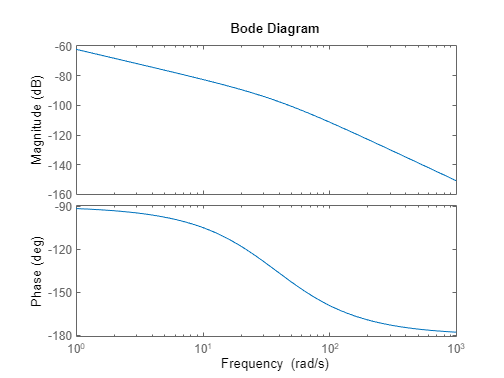

bode(wcs)

syms w

Wjw = ( 3226*(1i*w)^2+1.22*10^5*(1i*w)+9.648  ) / ( 1.118*10^5*(1i*w)^4 + 8.47*10^6*(1i*w)^3 + 1.605*10^8*(1i*w)^2 + 1.47*10^5*(1i*w)+10.65 )

$$Wjw = \frac{-3226\,w^{2}+122000\,w\,\mathrm{i}+\frac{1206}{125}}{\frac{7682837499084801\,w^{4}}{68719476736}-8470000\,w^{3}\,\mathrm{i}-160500000\,w^{2}+147000\,w\,\mathrm{i}+\frac{213}{20}}$$

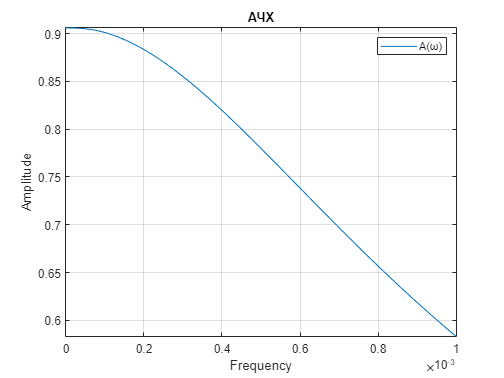

A1=sqrt(real(Wjw)^2+imag(Wjw)^2);

fplot(A1,[0,0.001])
grid on
xlabel("Frequency")
ylabel("Amplitude")
title("АЧХ")
legend("A(ω)")


[n, d] = tfdata(wos, 'v');